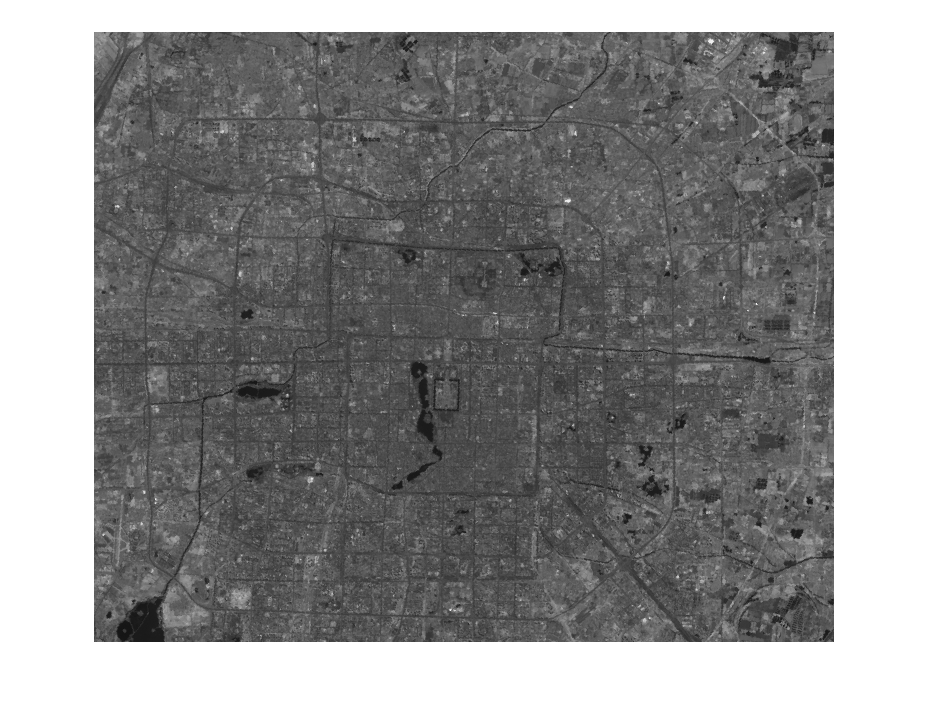

clear all;
clc;

% 导入图像
IMG=im2double(imread('C:\Users\L\Desktop\模式识别\input\beijing.tif'))*255;
row = length(IMG(:,1,:));   %图像排数
col = length(IMG(1,:,:));   %图像列数
bds = size(IMG,3);   %图像波段数

% 显示灰度图像
gray = mean(IMG,3)/255;

figure;
imshow(gray);

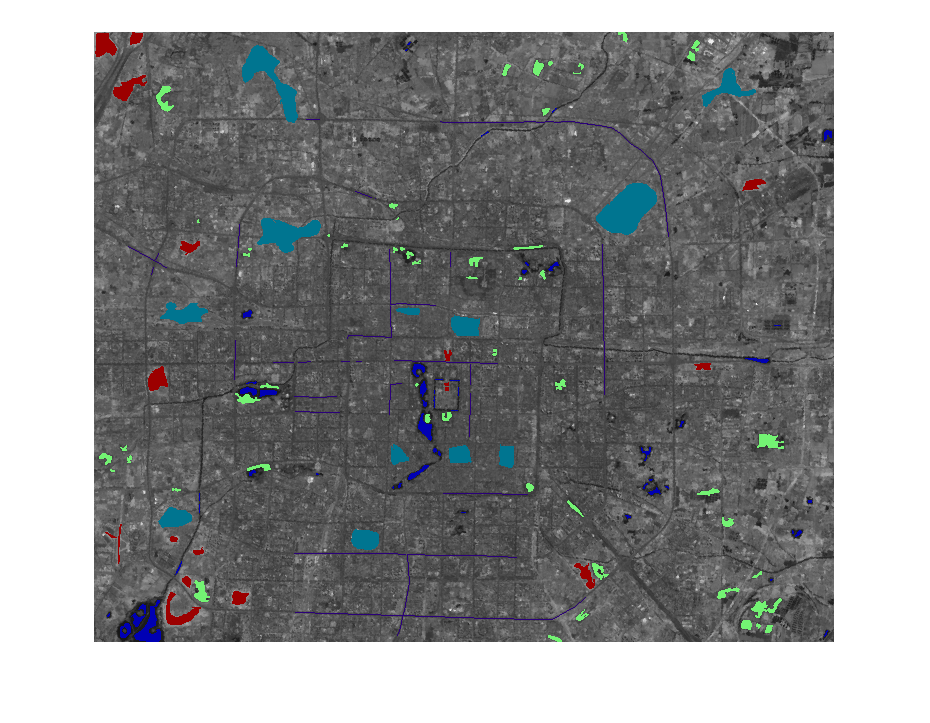

title('灰度图');

% 导入训练集
[class_data,nClass,names] = input_data('C:\Users\L\Desktop\模式识别\roi_data\roi_data001.csv', bds);

% 绘制训练集
res_pic = cat(3,gray,gray,gray);

% 随机选择颜色
if nClass ~= 5
    colors = add_rand_color(nClass);
else
    colors =[0	0	0.70443;%water
        0.45 0.95474	0.45;%tree
        0.61181	0	0;%ground
        0	0.45706	0.56407;% city
        0.16753	0	0.4835];% road
end

for class = 1:nClass
    % 调取x，y数组
    X = class_data{class,1}{1,1};
    Y = class_data{class,1}{1,2};
    
    for i = 1:class_data{class,1}{1,4}
        x = X(i)+1;
        y = Y(i)+1;
        res_pic(y,x,1) = colors(class,1);
        res_pic(y,x,2) = colors(class,2);
        res_pic(y,x,3) = colors(class,3);
    end
end


figure;
imshow(res_pic);

title('roi绘制');

% 下面开始进行分类算法
% 加载参数
[means, sigmas] = tran_bayes(nClass, bds, class_data);

% 进行分类
tic;                                
bar = waitbar(0,'分类中...');  
for x = 1:row
    for y = 1:col
        % 计算类别
        data =reshape(IMG(x,y,:),1,bds);
        result = eval_bayes(nClass, means, sigmas, data);
        
        % 染色
        res_pic(x,y,1) = colors(result,1);
        res_pic(x,y,2) = colors(result,2);
        res_pic(x,y,3) = colors(result,3);
        
    end
    % 显示进度
    str=['分类中...',num2str(100*x/row),'%'];
    waitbar(x/row,bar,str) 
end
close(bar);            
toc;

历时 6.769287 秒。


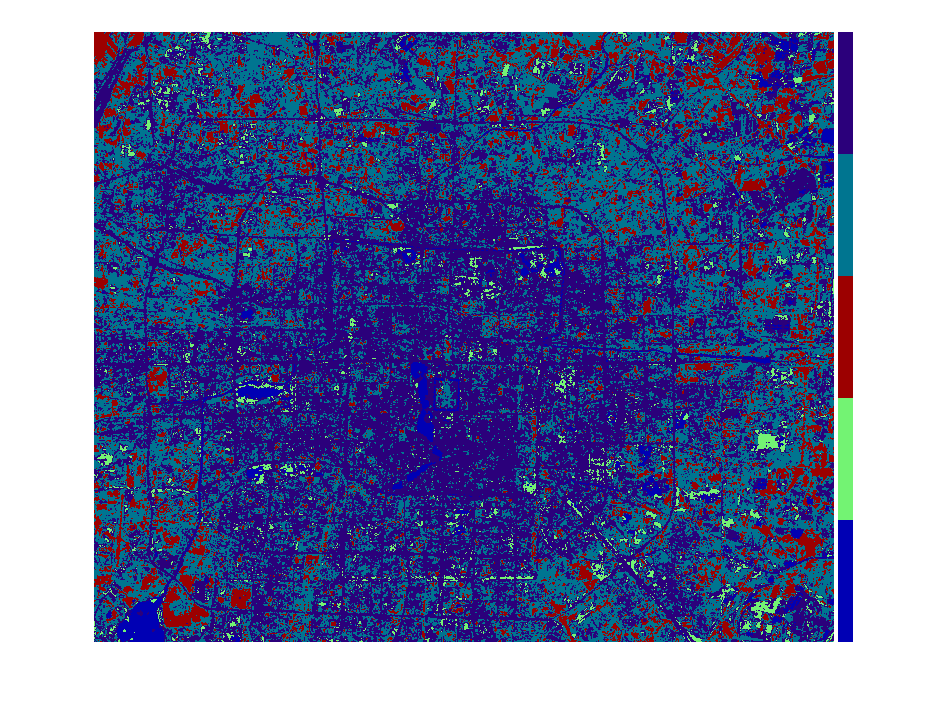


figure;
imshow(add_Color_bar(res_pic, colors)); 

title('贝叶斯分类器结果');

bar1 = waitbar(0,'计算混淆矩阵中...'); 
% 计算混淆矩阵
conf_matrix = zeros(nClass +1, nClass+1);
for class = 1:nClass
    for i = 1:class_data{class,1}{1,4}
        data = class_data{class,1}{1,3}(i,:);
        result = eval_bayes(nClass, means, sigmas, data);
        
        % 更新混淆矩阵
        conf_matrix(class, result) = conf_matrix(class, result) + 1;
    end
    str1=['计算混淆矩阵中...',num2str(100*class/nClass),'%'];
    waitbar(x/row,bar1,str1);
end
close(bar1);

for class = 1:nClass
    conf_matrix(nClass+1, class) = sum(conf_matrix(:, class));
    conf_matrix(class, nClass+1) = sum(conf_matrix(class, :));
end
conf_matrix(nClass+1,nClass+1) = sum(conf_matrix(nClass+1, :));

% 计算精度
correct = diag(conf_matrix);
acc = sum(correct(1:end-1))/conf_matrix(end,end);

disp('混淆矩阵为：');

混淆矩阵为：


disp(conf_matrix);

        1976           0           0           1          26        2003
          88        1927           4          35        1164        3218
           0           0        2307         426          28        2761
           2          23         987        4743        2532        8287
           0           8           0          23        1796        1827
        2066        1958        3298        5228        5546       18096



disp(strcat('正确率：',num2str(acc*100),'%'));

正确率：70.452%



% conf_matrix = array2table(conf_matrix)
